x=input('Enter x[n]:')

x =      1     2     3     4


m=length(x);
rev_x=flip(x)

rev_x =      4     3     2     1


X=[x,zeros(1,n)];
rev_X=[rev_x,zeros(1,n)];
for i=1:n+m
Y(i)=0;
for j=1:m
if(i-j+1>0)
Y(i)=Y(i)+X(j)*rev_X(i-j+1);
end
end
end
Y

Y = 1×21 logical array
   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0


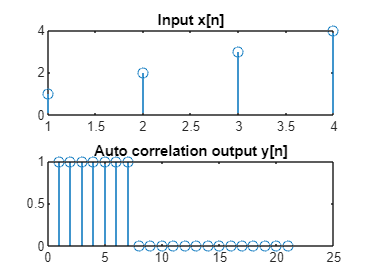

subplot(2,1,1)
stem(x);
title('Input x[n]');
subplot(2,1,2);
stem(Y);
title('Auto correlation output y[n]')


%cross
x=input('Enter x[n]:')
h=input('Enter h[n]:')
m=length(x);
n=length(h);
rev_h=flip(h)
X=[x,zeros(1,n)];
H=[rev_h,zeros(1,m)];
for i=1:n+m-1
Y(i)=0;
for j=1:m
if(i-j+1>0)
Y(i)=Y(i)+X(j)*H(i-j+1);
end
end
end
Y
subplot(2,2,1)
stem(x);
title('Input x[n]');
subplot(2,2,2);
stem(h);
title('Input h[n]')
subplot(2,2,3);
stem(Y);
title('Cross correlation output y[n]')

